%  
% Sound
% IIT madras prof devdas manon speech on intergral karam yoga
% Length :- 150 sec
% Recorded with stage mic

[samples, fsample] = audioread('TestAudio6.wav');

player = audioplayer(samples, fsample);
play(player);


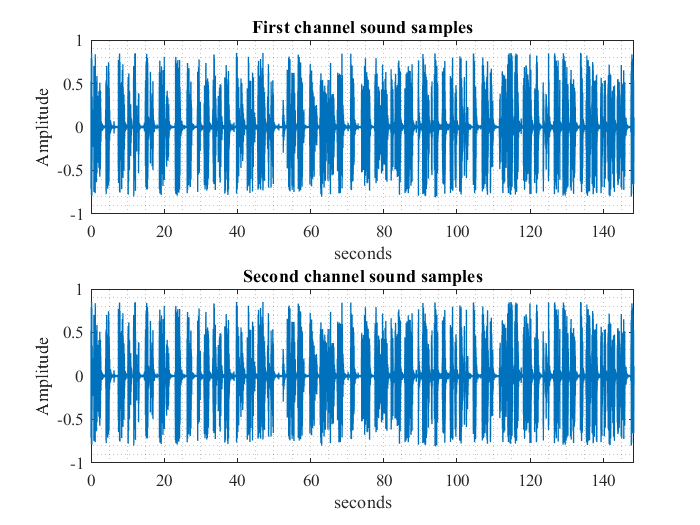

% Evidence handling and Initial assessment

% Waveform view
ShowWaveform(samples, fsample);

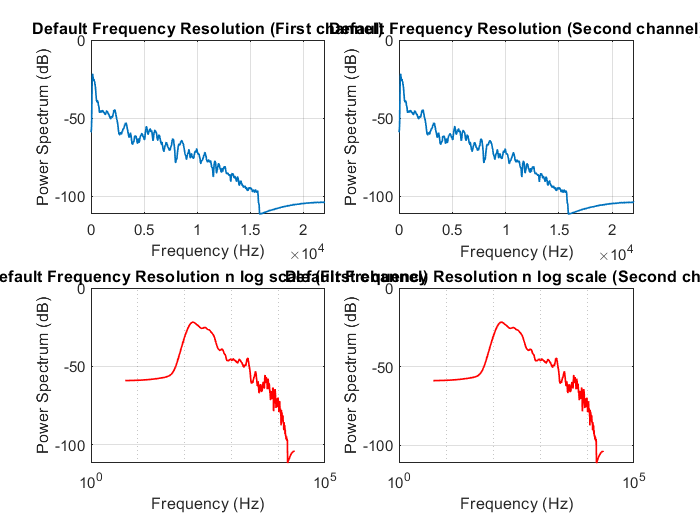


% PSD view
ShowPSD2(samples, fsample);


% Spectrogram view
% ShowSpectrogram(samples, fsample);
% Because it is too large size audio recording hence, spectrogram would
% take too much time

% Statistical view
audioStats(samples, fsample);

Max value in first Channel = 0.85208
Max value in second Channel = 0.85211
Minimum value in first Channel = -0.80884
Minimum value in second Channel = -0.80869
Mean value in first channel = -2.9071e-06
Mean value in second channel= -2.9065e-06
standard deviation of first channel= 0.15709
standard deviation of second channel= 0.15709
Variance of first channel= 0.024677
Variance of second channel= 0.024677
Power in first channel in dB= -16.077
Power in second channel in dB= -16.077
Sampling frequency in Hz =44100


% Audio feactures (MFCC)

% Mel Frequency capstral coefficient

[coeff, delta, deltaDelta, logf] = mfcc(samples, fsample);



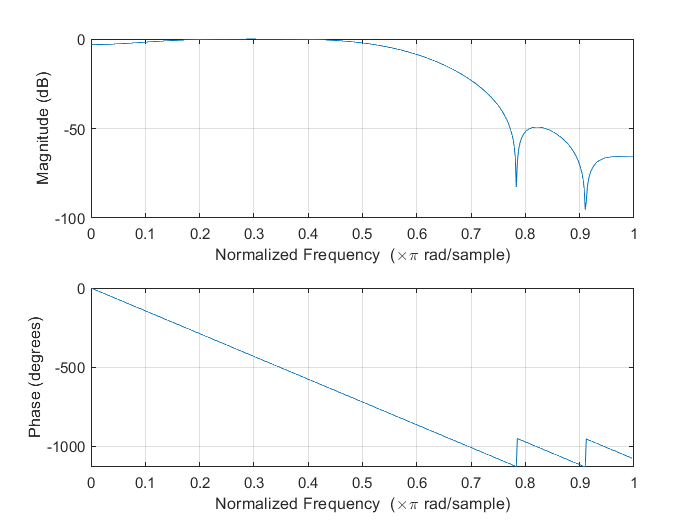

% Audio Enhancement techniques

% bandpass filter 
order =16;
level =1;
resultAudio = bandpassVocalFilter(samples, order,fsample, level);

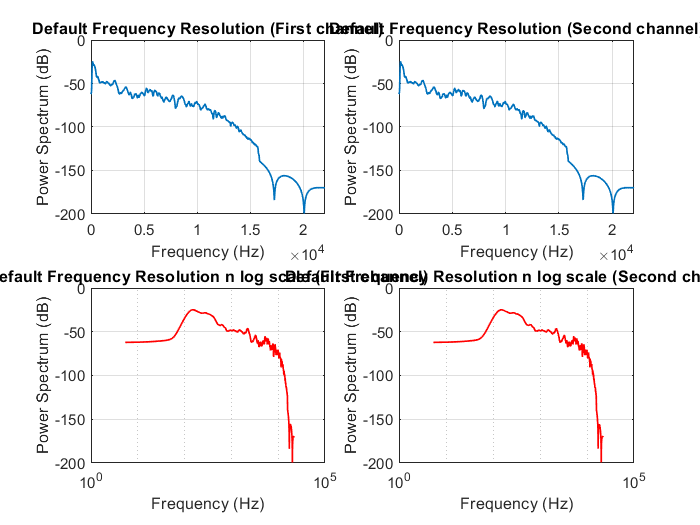


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio, fsample);


% Wiener filter approach

resultAudio2 = wienerFilter(resultAudio, fsample, 0.05);

The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440
The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


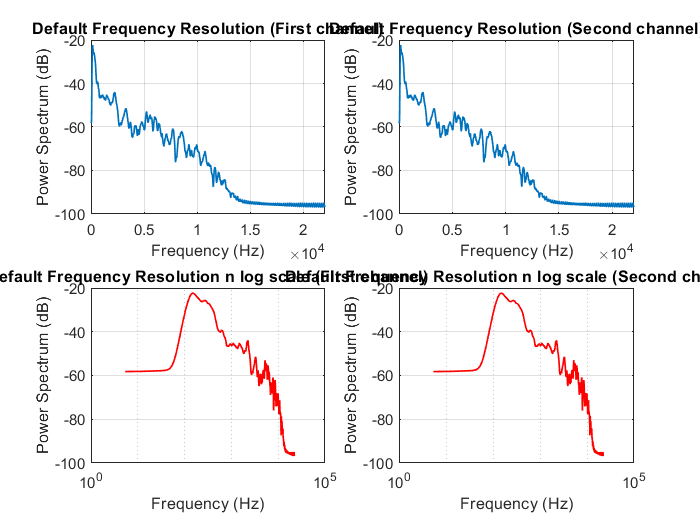


player = audioplayer(resultAudio2, fsample);
play(player);

ShowPSD2(resultAudio2, fsample);

% Compressor 
% 
% dRC = compressor(-20,5,'SampleRate',fsample);
% visualize(dRC)
% 
% resultAudio3 = dRC(resultAudio2);
% 
% player = audioplayer(resultAudio3, fsample);
% play(player);
% 
% ShowPSD2(resultAudio3, fsample);


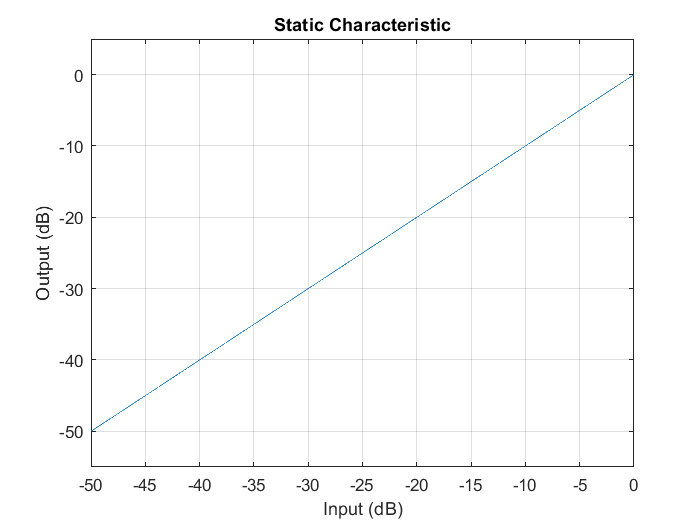

% Expender

dRC = expander(-60, 5, 'SampleRate',fsample);
visualize(dRC);

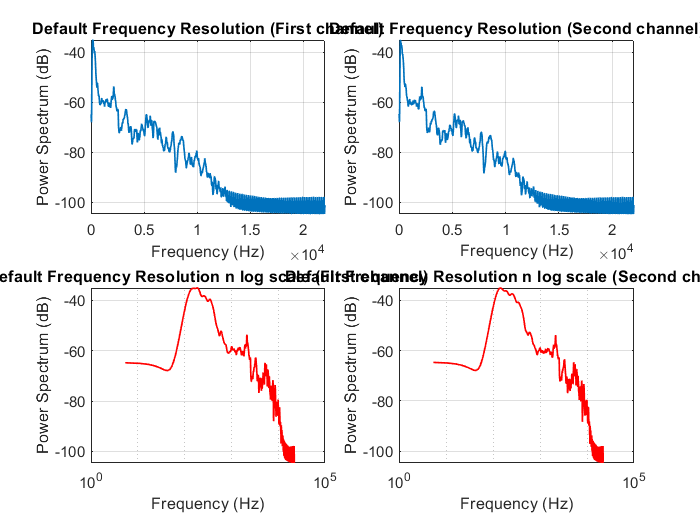


resultAudio4 = dRC(resultAudio2);


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio4, fsample);

audiowrite('enhancedTestAudio6.wav', resultAudio4, fsample);


